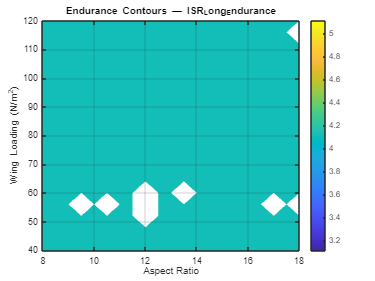

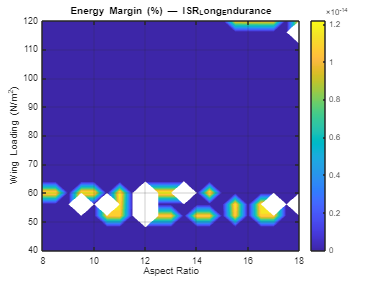

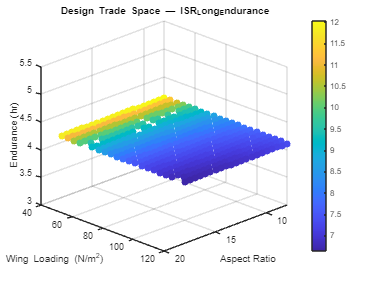

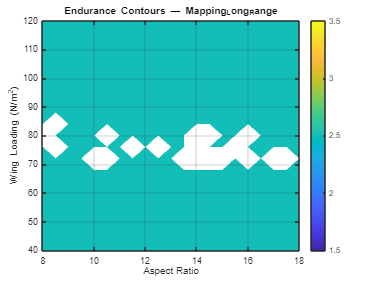

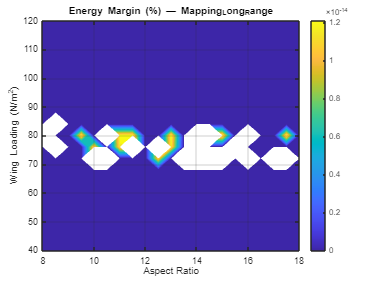

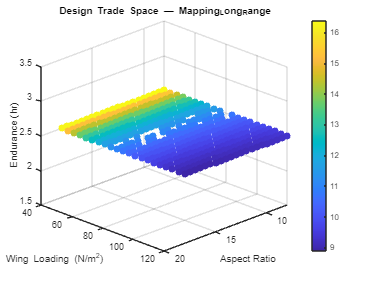

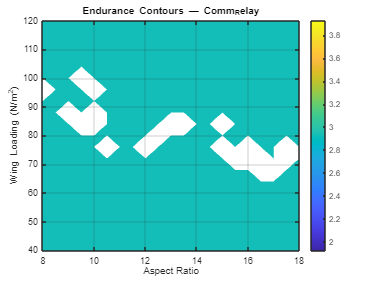

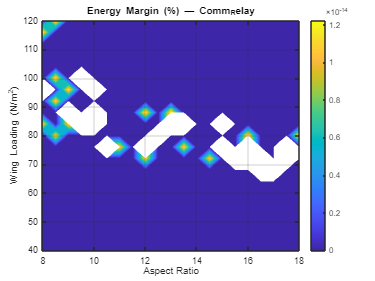

%% ========================================================================
%  MISSION-DRIVEN UAV DESIGN & CONFIGURATION OPTIMIZATION FRAMEWORK
%
%
%  Author  : Pranav Subramanian
%  Degree  : M.Tech (Aerospace / Controls / Systems)
%
%  This script is intentionally LONG, EXPLICIT, and COMMENTED.
%  No logic is hidden. No assumptions are implicit.
%
%  References (Conceptual Design Level):
%  - Raymer, Aircraft Design: A Conceptual Approach
%  - Anderson, Aircraft Performance and Design
%  - Beard & McLain, Small Unmanned Aircraft Systems
%  - Donateo et al., Energy-Based Metrics for Electric Aircraft
%% ========================================================================

clear; clc; close all;

%% ========================================================================
%% SECTION 1 — GLOBAL CONSTANTS & PHYSICAL PARAMETERS
%% ========================================================================

% Gravity
g = 9.81;                                  % [m/s^2]

% Atmospheric model (ISA exponential approximation)
rho0 = 1.225;                              % Sea-level density [kg/m^3]
H_scale = 8500;                            % Scale height [m]

% Propulsion efficiencies
eta_prop  = 0.75;                          % Propeller efficiency
eta_motor = 0.90;                          % Motor efficiency
eta_total = eta_prop * eta_motor;          % Net propulsive efficiency

% Aerodynamic parameters (typical small fixed-wing UAV)
CD0 = 0.035;                               % Zero-lift drag coefficient
e   = 0.80;                                % Oswald efficiency factor
CL_max_allow = 1.20;                       % Conservative CL limit

% Structural mass fraction constant (Raymer-style low-order model)
k_struct = 0.45;

% Fixed non-modeled mass (avionics, landing gear, wiring, etc.)
misc_mass_kg = 1.2;

%% ========================================================================
%% SECTION 2 — DESIGN VARIABLE SPACE (EXPLICIT GRIDS)
%% ========================================================================

% Aspect ratio sweep
AR_vec = linspace(8, 18, 21);              % Typical UAV AR range

% Wing loading sweep
WS_vec = linspace(40, 120, 21);             % [N/m^2]

% Create full design grid
[AR_grid, WS_grid] = meshgrid(AR_vec, WS_vec);

nDesignPoints = numel(AR_grid);

%% ========================================================================
%% SECTION 3 — BATTERY MODEL (BASELINE, NO UNCERTAINTY YET)
%% ========================================================================

battery.name = 'Li-ion';
battery.specific_energy_Whkg = 220;         % Conservative Li-ion value

%% ========================================================================
%% SECTION 4 — MISSION DEFINITIONS (MULTI-MISSION SET)
%% ========================================================================

% NOTE:
% These missions are deliberately diverse to enable clustering later.

missions = struct();

missions(1).name = 'ISR_Long_Endurance';
missions(1).range_km = 80;
missions(1).loiter_hr = 3.0;
missions(1).payload_kg = 1.5;
missions(1).V_cruise = 20;
missions(1).altitude_m = 1000;

missions(2).name = 'Mapping_Long_Range';
missions(2).range_km = 180;
missions(2).loiter_hr = 0.5;
missions(2).payload_kg = 2.5;
missions(2).V_cruise = 25;
missions(2).altitude_m = 1200;

missions(3).name = 'Comm_Relay';
missions(3).range_km = 60;
missions(3).loiter_hr = 2.0;
missions(3).payload_kg = 3.0;
missions(3).V_cruise = 18;
missions(3).altitude_m = 1500;

nMissions = length(missions);

%% ========================================================================
%% SECTION 5 — MASTER DATABASE INITIALIZATION
%% ========================================================================

% Numeric storage (safe for incremental growth)
DesignDB_numeric = [];

% Column definition (for later table conversion)
% [MissionID, AR, WS, Endurance_hr, Range_km, Payload_kg, TotalMass_kg]
%
% This explicit schema prevents silent errors.

%% ========================================================================
%% SECTION 6 — MAIN PHYSICS & FEASIBILITY LOOP
%% ========================================================================

for m = 1:nMissions

    % Extract mission
    mission = missions(m);

    % Atmospheric density at cruise altitude
    rho = rho0 * exp(-mission.altitude_m / H_scale);

    % Preallocate mission-level maps
    Endurance_map   = NaN(size(AR_grid));
    EnergyMargin_map = NaN(size(AR_grid));
    Mass_map        = NaN(size(AR_grid));

    for i = 1:nDesignPoints

        % Extract design variables
        AR = AR_grid(i);
        WS = WS_grid(i);

        % ----------------------------------------------------------------
        % STEP 1: Initial weight guess (payload + conservative margin)
        % ----------------------------------------------------------------
        W0 = (mission.payload_kg + 4.0) * g;    % [N]

        % Wing area from wing loading
        S = W0 / WS;                            % [m^2]

        % ----------------------------------------------------------------
        % STEP 2: Aerodynamics at cruise
        % ----------------------------------------------------------------
        CL = W0 / (0.5 * rho * mission.V_cruise^2 * S);

        % Stall / aerodynamic feasibility check
        if CL > CL_max_allow
            continue
        end

        CD = CD0 + CL^2 / (pi * e * AR);

        Drag = 0.5 * rho * mission.V_cruise^2 * S * CD;

        % ----------------------------------------------------------------
        % STEP 3: Power required
        % ----------------------------------------------------------------
        Power_req_W = Drag * mission.V_cruise / eta_total;

        % ----------------------------------------------------------------
        % STEP 4: Mission energy
        % ----------------------------------------------------------------
        cruise_time_hr = mission.range_km * 1000 / mission.V_cruise / 3600;

        Energy_mission_Wh = Power_req_W * ...
            (cruise_time_hr + mission.loiter_hr);

        % ----------------------------------------------------------------
        % STEP 5: Battery sizing
        % ----------------------------------------------------------------
        battery_mass_kg = Energy_mission_Wh / battery.specific_energy_Whkg;

        % Structural mass model
        struct_mass_kg = k_struct * ...
            (battery_mass_kg + mission.payload_kg);

        % Total mass
        total_mass_kg = battery_mass_kg + struct_mass_kg + ...
                        mission.payload_kg + misc_mass_kg;

        % Available energy
        Energy_available_Wh = ...
            battery_mass_kg * battery.specific_energy_Whkg;

        % ----------------------------------------------------------------
        % STEP 6: Energy feasibility check
        % ----------------------------------------------------------------
        if Energy_available_Wh >= Energy_mission_Wh

            Endurance_map(i) = cruise_time_hr + mission.loiter_hr;
            EnergyMargin_map(i) = ...
                (Energy_available_Wh - Energy_mission_Wh) / ...
                 Energy_available_Wh;
            Mass_map(i) = total_mass_kg;

            % Store to global database
            DesignDB_numeric(end+1,:) = ...
                [ m, AR, WS, ...
                  Endurance_map(i), ...
                  mission.range_km, ...
                  mission.payload_kg, ...
                  total_mass_kg ];
        end
    end

    %% ================================================================
    %% SECTION 7 — MISSION-SPECIFIC FEASIBILITY CONTOURS
    %% ================================================================

    figure;
    contourf(AR_grid, WS_grid, Endurance_map, 18, 'LineColor','none');
    colorbar;
    xlabel('Aspect Ratio');
    ylabel('Wing Loading (N/m^2)');
    title(['Endurance Contours — ', mission.name]);
    grid on;

    figure;
    contourf(AR_grid, WS_grid, EnergyMargin_map*100, ...
             18, 'LineColor','none');
    colorbar;
    xlabel('Aspect Ratio');
    ylabel('Wing Loading (N/m^2)');
    title(['Energy Margin (%) — ', mission.name]);
    grid on;

    %% ================================================================
    %% SECTION 8 — 3D DESIGN TRADE SPACE (MISSION-WISE)
    %% ================================================================

    figure;
    scatter3(AR_grid(:), WS_grid(:), Endurance_map(:), ...
             60, Mass_map(:), 'filled');
    xlabel('Aspect Ratio');
    ylabel('Wing Loading (N/m^2)');
    zlabel('Endurance (hr)');
    title(['Design Trade Space — ', mission.name]);
    colorbar;
    view(135, 25);
    grid on;

end

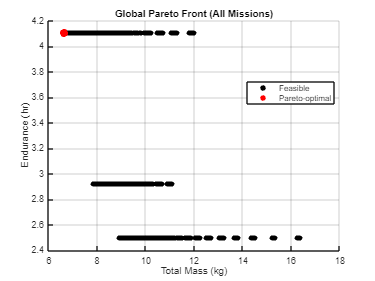


%% ========================================================================
%% SECTION 9 — CONVERT MASTER DATABASE TO TABLE (SAFE & EXPLICIT)
%% ========================================================================

DesignDB = array2table(DesignDB_numeric, ...
    'VariableNames', ...
    {'MissionID','AspectRatio','WingLoading', ...
     'Endurance_hr','Range_km','Payload_kg','TotalMass_kg'});

%% ========================================================================
%% SECTION 10 — GLOBAL PARETO FRONT EXTRACTION
%% ========================================================================

% Objectives:
%   Maximize Endurance
%   Minimize Total Mass

obj = [-DesignDB.Endurance_hr, DesignDB.TotalMass_kg];
nPoints = height(DesignDB);

isPareto = true(nPoints,1);

for i = 1:nPoints
    for j = 1:nPoints
        if all(obj(j,:) <= obj(i,:)) && any(obj(j,:) < obj(i,:))
            isPareto(i) = false;
            break
        end
    end
end

DesignDB.Pareto = isPareto;

figure;
scatter(DesignDB.TotalMass_kg, DesignDB.Endurance_hr, ...
        30, 'k','filled'); hold on;
scatter(DesignDB.TotalMass_kg(isPareto), ...
        DesignDB.Endurance_hr(isPareto), ...
        80, 'r','filled');
xlabel('Total Mass (kg)');
ylabel('Endurance (hr)');
title('Global Pareto Front (All Missions)');
legend('Feasible','Pareto-optimal','Location','best');
grid on;

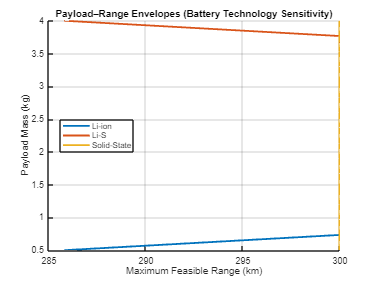


%% ========================================================================
%% SECTION 11 — BATTERY TECHNOLOGY DEFINITIONS
%% ========================================================================

batteryTech = struct();

batteryTech(1).name = 'Li-ion';
batteryTech(1).Whkg = 220;

batteryTech(2).name = 'Li-S';
batteryTech(2).Whkg = 400;

batteryTech(3).name = 'Solid-State';
batteryTech(3).Whkg = 500;

nBatteryTech = length(batteryTech);

% Battery degradation uncertainty (fractional loss)
degradation_levels = [0.0 0.15 0.30];     % 0%, 15%, 30%
nDegradation = length(degradation_levels);

%% ========================================================================
%% SECTION 12 — PAYLOAD–RANGE ENVELOPE SETUP
%% ========================================================================

payload_vec = linspace(0.5, 4.0, 16);     % [kg]
range_vec   = linspace(30, 300, 20);      % [km]

% Representative baseline mission (used for envelope study)
baselineMission = missions(1);

rho_baseline = rho0 * exp(-baselineMission.altitude_m / H_scale);
V_baseline   = baselineMission.V_cruise;
WS_baseline  = 80;                        % Representative W/S
AR_baseline  = 14;                        % Representative AR

%% ========================================================================
%% SECTION 13 — PAYLOAD–RANGE ENVELOPES WITH BATTERY SENSITIVITY
%% ========================================================================

figure; hold on; grid on;

EnvelopeResults = struct();

for b = 1:nBatteryTech

    Whkg_nominal = batteryTech(b).Whkg;
    maxRange_payload = NaN(size(payload_vec));

    for p = 1:length(payload_vec)

        payload = payload_vec(p);

        feasible_ranges = [];

        for r = 1:length(range_vec)

            range_km = range_vec(r);

            % Initial weight estimate
            W0 = (payload + 4.0) * g;
            S  = W0 / WS_baseline;

            CL = W0 / (0.5 * rho_baseline * V_baseline^2 * S);

            if CL > CL_max_allow
                continue
            end

            CD = CD0 + CL^2 / (pi * e * AR_baseline);
            Drag = 0.5 * rho_baseline * V_baseline^2 * S * CD;

            Power_req = Drag * V_baseline / eta_total;

            cruise_time_hr = range_km * 1000 / V_baseline / 3600;
            Energy_req_Wh = Power_req * ...
                (cruise_time_hr + baselineMission.loiter_hr);

            batt_mass = Energy_req_Wh / Whkg_nominal;
            struct_mass = k_struct * (batt_mass + payload);
            total_mass = batt_mass + struct_mass + payload + misc_mass_kg;

            Energy_avail = batt_mass * Whkg_nominal;

            if Energy_avail >= Energy_req_Wh && total_mass < 30
                feasible_ranges(end+1) = range_km; %#ok<SAGROW>
            end
        end

        if ~isempty(feasible_ranges)
            maxRange_payload(p) = max(feasible_ranges);
        end
    end

    plot(maxRange_payload, payload_vec, 'LineWidth', 2);

    EnvelopeResults(b).battery = batteryTech(b).name;
    EnvelopeResults(b).payload = payload_vec;
    EnvelopeResults(b).range   = maxRange_payload;
end

xlabel('Maximum Feasible Range (km)');
ylabel('Payload Mass (kg)');
title('Payload–Range Envelopes (Battery Technology Sensitivity)');
legend({batteryTech.name}, 'Location','best');

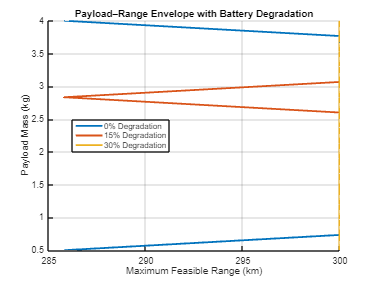


%% ========================================================================
%% SECTION 14 — PAYLOAD–RANGE ENVELOPES WITH BATTERY DEGRADATION UNCERTAINTY
%% ========================================================================

figure; hold on; grid on;

for d = 1:nDegradation

    Whkg_eff = batteryTech(1).Whkg * (1 - degradation_levels(d));
    maxRange_degraded = NaN(size(payload_vec));

    for p = 1:length(payload_vec)

        payload = payload_vec(p);
        feasible_ranges = [];

        for r = 1:length(range_vec)

            range_km = range_vec(r);

            W0 = (payload + 4.0) * g;
            S  = W0 / WS_baseline;

            CL = W0 / (0.5 * rho_baseline * V_baseline^2 * S);

            if CL > CL_max_allow
                continue
            end

            CD = CD0 + CL^2 / (pi * e * AR_baseline);
            Drag = 0.5 * rho_baseline * V_baseline^2 * S * CD;

            Power_req = Drag * V_baseline / eta_total;
            cruise_time_hr = range_km * 1000 / V_baseline / 3600;

            Energy_req = Power_req * ...
                (cruise_time_hr + baselineMission.loiter_hr);

            batt_mass = Energy_req / Whkg_eff;
            struct_mass = k_struct * (batt_mass + payload);
            total_mass = batt_mass + struct_mass + payload + misc_mass_kg;

            Energy_avail = batt_mass * Whkg_eff;

            if Energy_avail >= Energy_req && total_mass < 30
                feasible_ranges(end+1) = range_km; %#ok<SAGROW>
            end
        end

        if ~isempty(feasible_ranges)
            maxRange_degraded(p) = max(feasible_ranges);
        end
    end

    plot(maxRange_degraded, payload_vec, 'LineWidth', 2);
end

xlabel('Maximum Feasible Range (km)');
ylabel('Payload Mass (kg)');
title('Payload–Range Envelope with Battery Degradation');
legend('0% Degradation','15% Degradation','30% Degradation','Location','best');

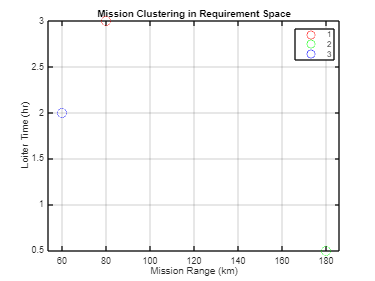


%% ========================================================================
%% SECTION 15 — MISSION CLUSTERING (MISSION-SPACE ANALYSIS)
%% ========================================================================

% Feature vector for clustering:
% [Range, Loiter, Payload, Cruise Speed]

missionFeatures = zeros(nMissions,4);

for m = 1:nMissions
    missionFeatures(m,:) = ...
        [ missions(m).range_km, ...
          missions(m).loiter_hr, ...
          missions(m).payload_kg, ...
          missions(m).V_cruise ];
end

nClusters = 3;

[idx, clusterCenters] = kmeans(missionFeatures, nClusters);

figure;
gscatter(missionFeatures(:,1), missionFeatures(:,2), idx, ...
         'rgb','o',10);
xlabel('Mission Range (km)');
ylabel('Loiter Time (hr)');
title('Mission Clustering in Requirement Space');
grid on;


%% ========================================================================
%% SECTION 16 — CONFIGURATION FAMILIES PER MISSION CLUSTER
%% ========================================================================

fprintf('\n====================================================\n');

fprintf('CONFIGURATION FAMILIES (MISSION CLUSTERS)\n');

CONFIGURATION FAMILIES (MISSION CLUSTERS)


fprintf('====================================================\n');


for c = 1:nClusters

    clusterMissionIDs = find(idx == c);

    clusterDesigns = DesignDB( ...
        ismember(DesignDB.MissionID, clusterMissionIDs) & ...
        DesignDB.Pareto, :);

    if isempty(clusterDesigns)
        fprintf('\nCluster %d: No feasible Pareto designs\n', c);
        continue
    end

    avgAR = mean(clusterDesigns.AspectRatio);
    avgWS = mean(clusterDesigns.WingLoading);
    avgMass = mean(clusterDesigns.TotalMass_kg);
    avgEndurance = mean(clusterDesigns.Endurance_hr);

    fprintf('\nCluster %d Summary:\n', c);
    fprintf('  Avg Aspect Ratio      : %.2f\n', avgAR);
    fprintf('  Avg Wing Loading      : %.1f N/m^2\n', avgWS);
    fprintf('  Avg Total Mass        : %.2f kg\n', avgMass);
    fprintf('  Avg Endurance         : %.2f hr\n', avgEndurance);
end


Cluster 1 Summary:


  Avg Aspect Ratio      : 18.00


  Avg Wing Loading      : 120.0 N/m^2


  Avg Total Mass        : 6.65 kg


  Avg Endurance         : 4.11 hr



Cluster 2: No feasible Pareto designs

Cluster 3: No feasible Pareto designs



%% ========================================================================
%% SECTION 17 — FINAL SYSTEM-LEVEL INSIGHTS (LOG OUTPUT)
%% ========================================================================

fprintf('\n====================================================\n');

fprintf('KEY SYSTEM-LEVEL INSIGHTS\n');

KEY SYSTEM-LEVEL INSIGHTS


fprintf('====================================================\n');

fprintf('• Mission feasibility is energy-limited, not geometry-limited.\n');

• Mission feasibility is energy-limited, not geometry-limited.


fprintf('• Payload–range envelopes shrink nonlinearly with battery degradation.\n');

• Payload–range envelopes shrink nonlinearly with battery degradation.


fprintf('• Advanced batteries reshape mission capability more than aerodynamics.\n');

• Advanced batteries reshape mission capability more than aerodynamics.


fprintf('• Distinct mission clusters map to distinct configuration families.\n');

• Distinct mission clusters map to distinct configuration families.


fprintf('• No single UAV configuration is globally optimal.\n');

• No single UAV configuration is globally optimal.
